ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');
allCells = [ups;downs];

priorityOrder_1 = {'Flash'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'Intracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Intracellular', 'Excitation'};
mustHave_2b = {'Inhibition'};
cantHave_1 = [];
cantHave_2 = {'Extracellular', 'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %

peaksEx = zeros(0, 2);
chargesEx = zeros(0, 2);
cellsUsed = {};
for i = 1:size(allCells, 1)
    struct_i = allCells{i, 2};
    cname = allCells{i, 1};
    
    if ~isfield(struct_i, 'PairedCells')
        continue
    end
    partnerName = struct_i.PairedCells{1};
    
    if ~ismember(partnerName, allCells(:, 1))
        continue
    end
    
    if ismember(cname, cellsUsed) || ismember(partnerName, cellsUsed)
        continue
    end
    cellsUsed = [cellsUsed, {cname}, {partnerName}];
    
    partnerStruct = allCells{strcmp(partnerName, allCells(:, 1)), 2};
    
    [loc_i, pass_i] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_partner, pass_partner] = getLoc(partnerStruct, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass_i || pass_partner
        continue
    end
    
    peakFlash_Ex_Up = mean(loc_i.Analysis_Results.ON_maxNegativePeakByEpoch);
    chargeFlash_Ex_Up = mean(loc_i.Analysis_Results.totalChargeByEpoch);
    
    peakFlash_Ex_Down = mean(loc_partner.Analysis_Results.ON_maxNegativePeakByEpoch);
    chargeFlash_Ex_Down = mean(loc_partner.Analysis_Results.totalChargeByEpoch);
    
    peaksEx = [peaksEx;peakFlash_Ex_Up, peakFlash_Ex_Down];
    chargesEx = [chargesEx; chargeFlash_Ex_Up, chargeFlash_Ex_Down];
end

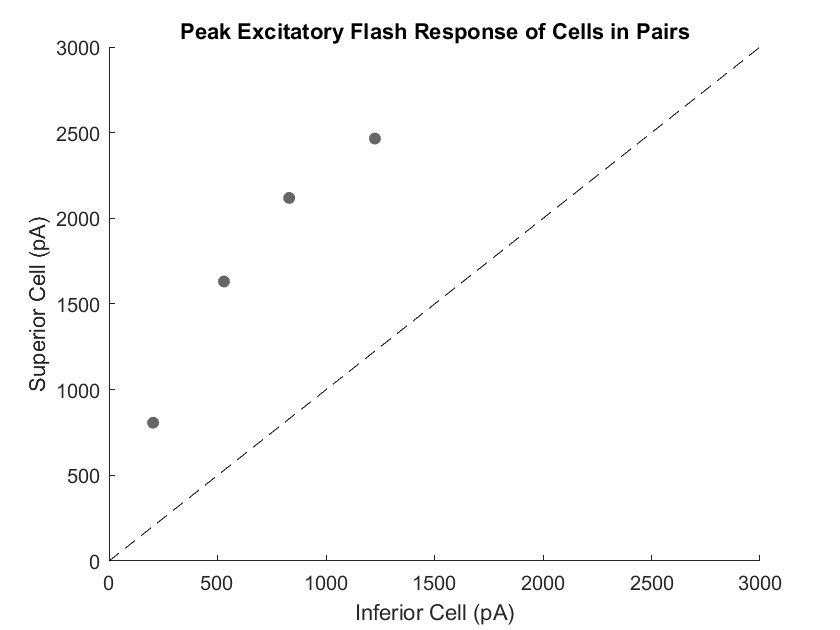


figure
title('Peak Excitatory Flash Response of Cells in Pairs')
hold on
scatter(-peaksEx(:, 1), -peaksEx(:,2), 'filled', 'k', 'MarkerFaceAlpha', 0.6)
plot([0 3000], [0 3000], '--k')
xlabel('Inferior Cell (pA)')
ylabel('Superior Cell (pA)')

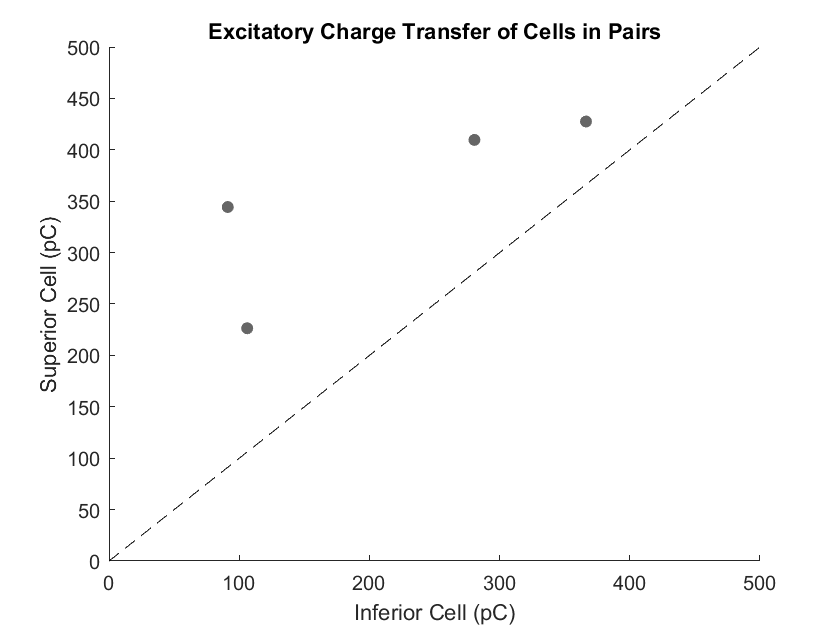

figure
title('Excitatory Charge Transfer of Cells in Pairs')
hold on
scatter(-chargesEx(:, 1), -chargesEx(:,2), 'filled', 'k', 'MarkerFaceAlpha', 0.6)
plot([0 500], [0 500], '--k')
xlabel('Inferior Cell (pC)')
ylabel('Superior Cell (pC)')

## Inhibition


peaksInh = zeros(0, 2);
chargesInh = zeros(0, 2);
cellsUsed = {};
for i = 1:size(allCells, 1)
    struct_i = allCells{i, 2};
    cname = allCells{i, 1};
    
    if ~isfield(struct_i, 'PairedCells')
        continue
    end
    partnerName = struct_i.PairedCells{1};
    
    if ~ismember(partnerName, allCells(:, 1))
        continue
    end
    
    if ismember(cname, cellsUsed) || ismember(partnerName, cellsUsed)
        continue
    end
    cellsUsed = [cellsUsed, {cname}, {partnerName}];
    
    partnerStruct = allCells{strcmp(partnerName, allCells(:, 1)), 2};
    
    [loc_i, pass_i] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    [loc_partner, pass_partner] = getLoc(partnerStruct, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    
    if pass_i || pass_partner
        continue
    end
    
    peakFlash_Inh_Up = mean(loc_i.Analysis_Results.ON_maxPositivePeakByEpoch);
    chargeFlash_Inh_Up = mean(loc_i.Analysis_Results.totalChargeByEpoch);
    
    peakFlash_Inh_Down = mean(loc_partner.Analysis_Results.ON_maxPositivePeakByEpoch);
    chargeFlash_Inh_Down = mean(loc_partner.Analysis_Results.totalChargeByEpoch);
    
    peaksInh = [peaksInh;peakFlash_Inh_Up, peakFlash_Inh_Down];
    chargesInh = [chargesInh; chargeFlash_Inh_Up, chargeFlash_Inh_Down];
end

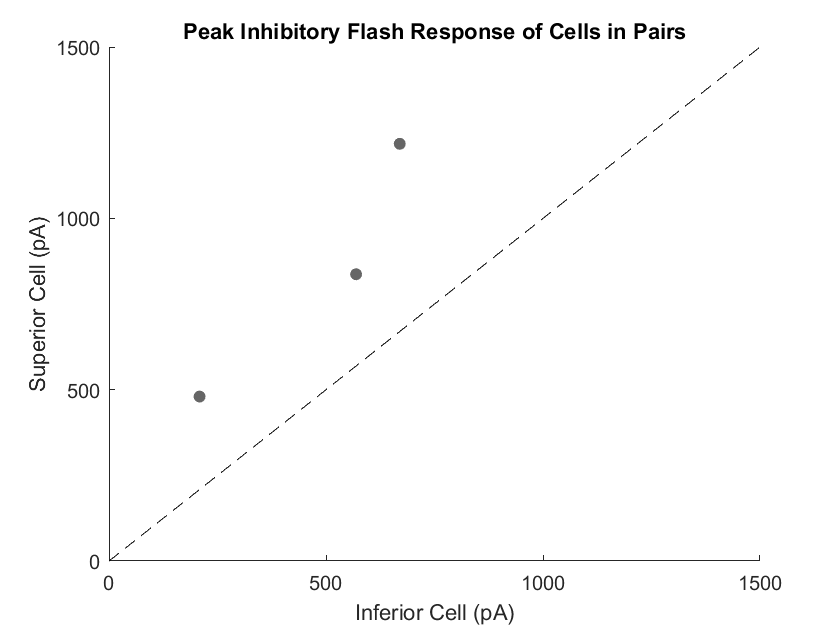


figure
title('Peak Inhibitory Flash Response of Cells in Pairs')
hold on
scatter(peaksInh(:, 1), peaksInh(:,2), 'filled', 'k', 'MarkerFaceAlpha', 0.6)
plot([0 1500], [0 1500], '--k')
xlabel('Inferior Cell (pA)')
ylabel('Superior Cell (pA)')

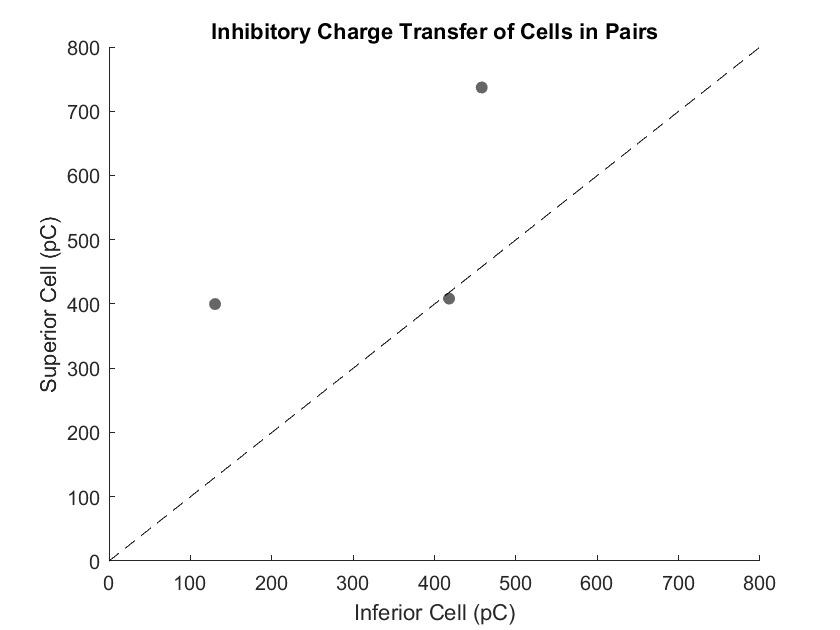

figure
title('Inhibitory Charge Transfer of Cells in Pairs')
hold on
scatter(chargesInh(:, 1), chargesInh(:,2), 'filled', 'k', 'MarkerFaceAlpha', 0.6)
plot([0 800], [0 800], '--k')
xlabel('Inferior Cell (pC)')
ylabel('Superior Cell (pC)')